## Construcción de la integral Madre y se añande el lamba

### Primero  defino el número de muestras en el intervalo [0 .. 1]; 

se define j que nos da el número de ondas.

j = 4;    
numero_muestras= 1024 %(j^2)*10;   

numero_muestras = 1024

disp(numero_muestras)

        1024



t=zeros(numero_muestras,1)

t =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Construyo el vector de tiempo

for i=2:1:numero_muestras   %    construyo el vector de tiempo
    t(i) = t(i-1)+1/numero_muestras;
end


### Construyo la integral Madre original

delta=zeros(numero_muestras,1)

delta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


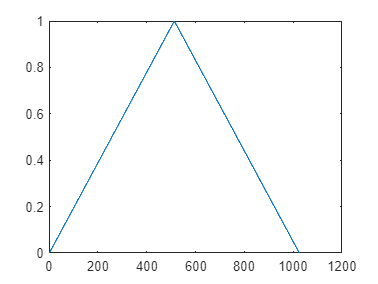

for i=1:1:numero_muestras    
    if t(i) <= 0.5
        delta(i) = 2*t(i);
    else
        delta(i) = 2*(1-t(i));
    end    
end

plot(delta)

### Calculo el índice K'esismo  y los n elementos 

k_esimo = 2^j;          
k=zeros(k_esimo,1);
for i=0:1:k_esimo-1
    k(i+1)=i; 
end                     %  0 <= k < 2^j

disp(k);

     0
     1
     2
     3
     4
     5
     6
     7
     8
     9
    10
    11
    12
    13
    14
    15



num_k=size(k,1);

n = zeros(num_k,1);
for z=1:1:num_k
    n(z)= 2^j + k(z);
end                     % n = 2^j + k

disp(n);

    16
    17
    18
    19
    20
    21
    22
    23
    24
    25
    26
    27
    28
    29
    30
    31



Calculo el rango para cada onda

rango = round(numero_muestras/(2^j));
    

### Calculamos cada integral y se grafican

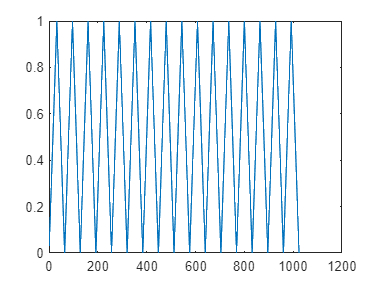

delta_n = zeros(num_k,1);


for w=1:1:num_k

    lamba_n = 0.5*(2^(-j/2));

    for i=1+(rango)*(w-1):1:rango+(rango)*(w-1)
        delta_n(i) = delta((2^j)*i-k(w)*(numero_muestras));
    end
        plot(delta_n);
end

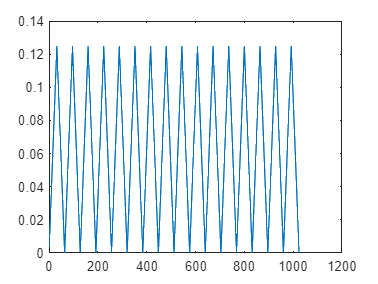


delta_n = lamba_n*delta_n;
plot(delta_n);